# Autoencoder airfoil generator

## Train an autoencoder

unzip('airfoils.zip', 'airfoils');
% encoder = train_selig('airfoils', chebyshevs(5), 5, 100, 'MaxEpochs', 10000);
encoder = train_selig_new('airfoils', chebyshevs(5), 5, 100, 'MaxEpochs', 10000);

## Set parameter variables (live reload)

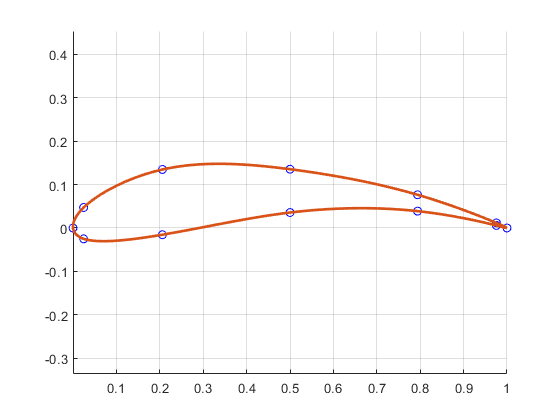

a1 = 0.186;
a2 = 0.107;
a3 = 0.101;
a4 = 0.394;
a5 = 0.077;
ch_xx = chebyshevs(5);
af = (decode(encoder, [a1; a2; a3; a4; a5])/100)';
ex_xx = [ 1 fliplr(ch_xx) 0 ch_xx 1];
ex_yy = [0 af(1:5) 0 af(6:10) 0];
clf
hold on
plot(ex_xx, ex_yy, 'bo');
curve = cscvn([ex_xx;ex_yy]);
fnplt(curve)
hold off
axis equal
grid on

## Set parameter variables (live reload)

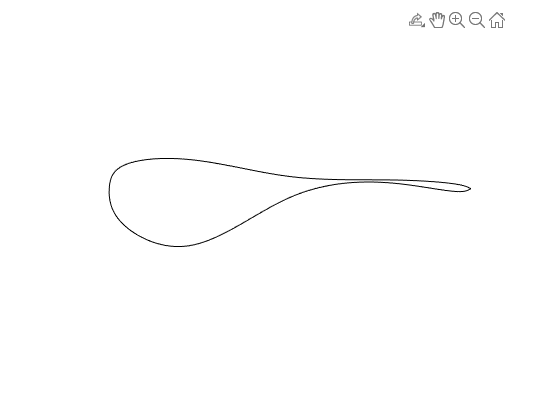

a1 = 0.306;
a2 = 0.071;
a3 = 0.201;
a4 = 0.232;
a5 = 0.69;
ch_xx = chebyshevs(5);
% plot(decodeAirfoil_new(encoder, [a1; a2; a3; a4; a5], 0.01, ch_xx, 200), 'FaceColor','white')
plot(decodeAirfoil_new(encoder, rand(5,1), 0.01, ch_xx, 200), 'FaceColor','white')
axis equal
axis off

## Set parameter variables (4)

a1 = 0.193;
a2 = 0.9;
a3 = 0.034;
a4 = 0.9;
a5 = 0;

af = (decode(encoder, [a1; a2; a3; a4])/100)';

Error using Autoencoder/decode (line 215)
Input data for decode must be a matrix where the number of rows is the same as the 'HiddenSize' property of the autoencoder, encoder.

ex_xx = [ 1 fliplr(xxnodes) 0 xxnodes 1];
ex_yy = [0 af(1:4) 0 af(5:8) 0];
clf
hold on
plot(ex_xx, ex_yy, 'bo');
curve = cscvn([ex_xx;ex_yy]);
fnplt(curve)
hold off
axis equal
grid on

Set all parameters (live reload)

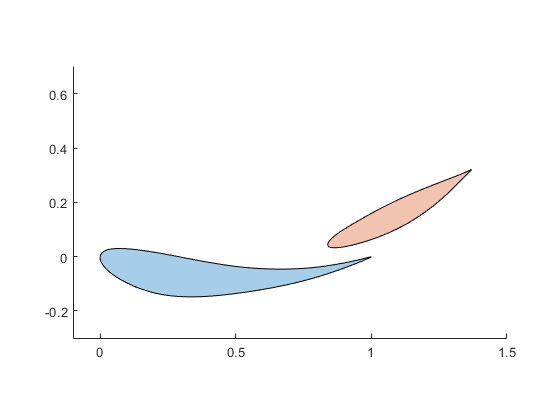

e1_1 = 0.186;
e1_2 = 0.107;
e1_3 = 0.101;
e1_4 = 0.394;
e1_5 = 0.077;
e2_1 = 0.099;
e2_2 = 0.08;
e2_3 = 0.202;
e2_4 = 0.147;
e2_5 = 0.196;
a1 = 0;
a2 = 28;
x2 = 0.16;
y2 = 0.01;
s2 = 0.6;
ch_xx = chebyshevs(5);
el1 = decodeAirfoil(encoder, [e1_1; e1_2; e1_3; e1_4; e1_5], 0.01, ch_xx);
el2 = decodeAirfoil(encoder, [e2_1; e2_2; e2_3; e2_4; e2_5], 0.01, ch_xx);
[e1m, e2m] = twoairfoils(el1, a1, el2, a2, x2, y2, s2);
plot([e1m e2m])
axis equal
xlim([-0.1 1.5])
ylim([-0.3 0.7])

## sda

e1_1 = 0.166;
e1_2 = 0.9;
e1_3 = 0.086;
e1_4 = 0.9;
e1_5 = 0.117;
e2_1 = 0;
e2_2 = 0.068;
e2_3 = 0.092;
e2_4 = 0.282;
e2_5 = 0.068;
a1 = 8;
a2 = 44;
x2 = 0.14;
y2 = 0.06;
s2 = 0.6;

ch_xx = chebyshevs(5);
el1 = decodeAirfoil(encoder, [e1_1; e1_2; e1_3; e1_4], 0.01, xxnodes);

Unrecognized function or variable 'xxnodes'.

el2 = decodeAirfoil(encoder, [e2_1; e2_2; e2_3; e2_4], 0.01, xxnodes);
[e1m, e2m, ltot] = twoairfoils(el1, a1, el2, a2, x2, y2, s2);
plot([e1m e2m])
axis equal
xlim([-0.1 1.5])
ylim([-0.3 0.7])
 


## fs

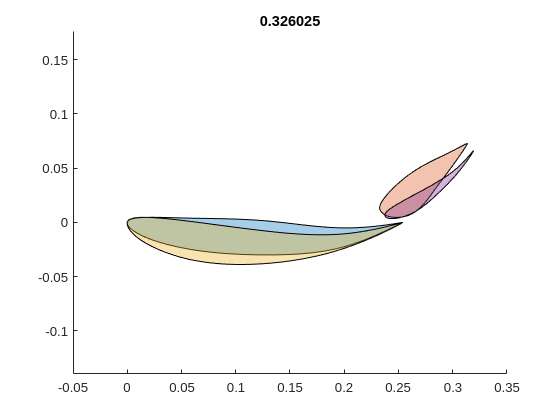

e1_1 = 0.186;
e1_2 = 0.107;
e1_3 = 0.101;
e1_4 = 0.394;
e1_5 = 0.077;
e2_1 = 0.186;
e2_2 = 0.107;
e2_3 = 0.172;
e2_4 = 0.202;
e2_5 = 0.031;
gap = 0.02;
overlap = 0.05;
s2 = 0.4;
clf;
ch_xx = chebyshevs(5);
% el1 = decodeAirfoil(encoder, [e1_1; e1_2; e1_3; e1_4; e1_5], 0.01, ch_xx, 200);
% el2 = decodeAirfoil(encoder, [e2_1; e2_2; e2_3; e2_4; e2_5], 0.01, ch_xx, 200);
el1 = decodeAirfoil_new(encoder, val1', 0.01, ch_xx, 200);
el2 = decodeAirfoil_new(encoder, val2', 0.01, ch_xx, 200);
[e1m, e2m, Ltot] = twoairfoils_new(el1, el2, gap, overlap, s2, 1);
e1s = scale(e1m, 0.254);
e2s = scale(e2m, 0.254);
Ltots = Ltot*0.254;
bi1 = [0.353023 0.0159164 0.138461 0.0230857 0.0485659];
bi2 = [0.411729 0.347414 0.15855 0.475111 0.017223];
ba1 = decodeAirfoil_new(encoder, bi1', 0.01, ch_xx, 200);
ba2 = decodeAirfoil_new(encoder, bi2', 0.01, ch_xx, 200);
[b1m, b2m, b2tot] = twoairfoils_new(ba1, ba2, gap, overlap, s2, 1);
b1s = scale(b1m, 0.254);
b2s = scale(b2m, 0.254);
plot([b1s b2s])
hold on
plot([e1s e2s])
hold off
axis equal
xlim([-0.05 0.35])
title(Ltots)